# Strogatz chapter7 LIMIT CYCLES

#### 7.1 Examples

ファン・デル・ポール方程式


$$\ddot{x} +\mu \left(x^2 -1\right)\dot{x} +x=0$$


状態方程式に変換


$$\begin{array}{l}
\dot{x} =y\\
\dot{y} =-x-\mu \left(x^2 -1\right)y
\end{array}$$


mu = 1.4

mu = 1.4000

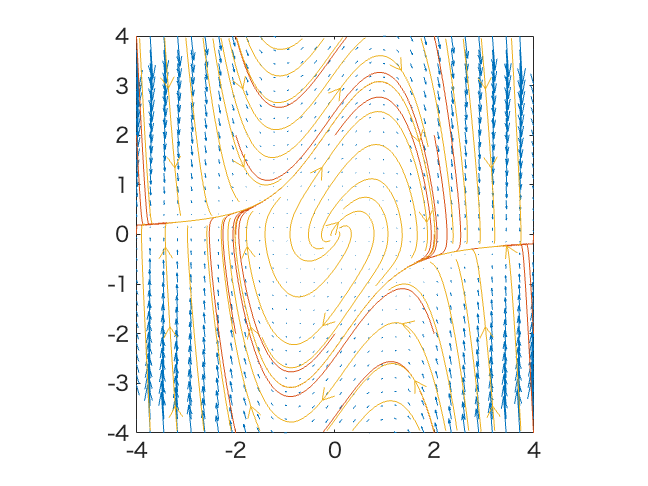

max = 4;

x = linspace(-max,max,30);
y = linspace(-max,max,30);
[X,Y] = meshgrid(x,y);

U = Y;
V = - X - mu*(X.^2-1).*Y;

quiver(X,Y,U,V,3)
axis equal

x0set = linspace(-max,max,5);
y0set = linspace(-max,max,5);
[startX,startY] = meshgrid(x0set,y0set);
streamline(X,Y,U,V,startX,startY)
streamslice(X,Y,U,V,0.5)

xlim([-max max])
ylim([-max max])

#### 7.3 Poincare-Bendixon Theorem


$$\begin{array}{l}
\dot{x} =-x+ay+x^2 y\\
\dot{y} =b-ay-x^2 y
\end{array}$$


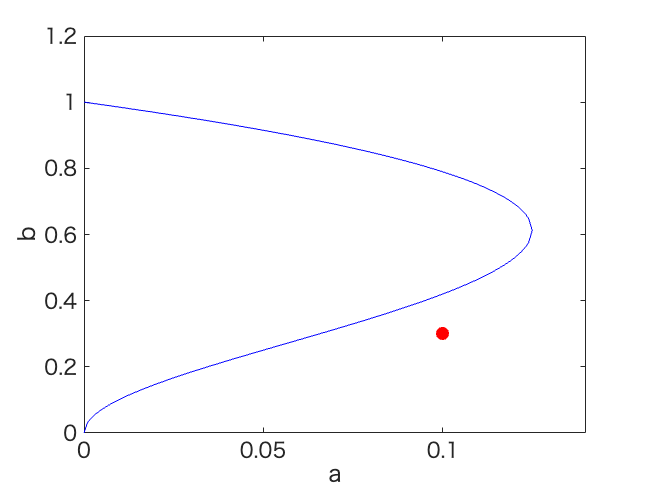

a = 0.1;
b = 0.3;
aset = 0:1e-3:0.125;
bset1 = []; bset2 = [];
for i=1:length(aset)
    bset1 = [bset1; aset(i), sqrt(0.5*(1 - 2*aset(i) + sqrt(1-8*aset(i))))];
    bset2 = [bset2; aset(i), sqrt(0.5*(1 - 2*aset(i) - sqrt(1-8*aset(i))))];
end
figure
plot(bset1(:,1),bset1(:,2),'Color','b')
hold on
plot(bset2(:,1),bset2(:,2),'Color','b')
plot(a,b,'ro','MarkerFaceColor','r')
xlim([0 0.14])
ylim([0 1.2])
xlabel('a'); ylabel('b');

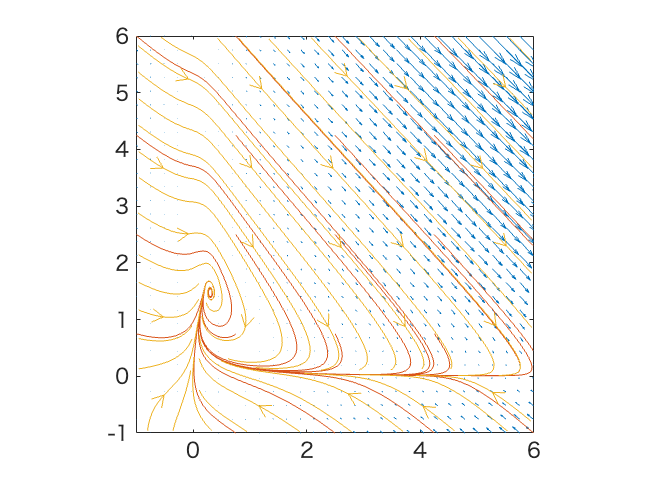


min = -1;
max = 6;

x = linspace(min,max,30);
y = linspace(min,max,30);
[X,Y] = meshgrid(x,y);

U = - X + a*Y + X.^2.*Y;
V = b - a*Y - X.^2.*Y;

figure
quiver(X,Y,U,V,3)
axis equal

x0set = linspace(min,max,5);
y0set = linspace(min,max,5);
[startX,startY] = meshgrid(x0set,y0set);
streamline(X,Y,U,V,startX,startY)
streamslice(X,Y,U,V,0.5)

xlim([min max])
ylim([min max])